# Problem 1

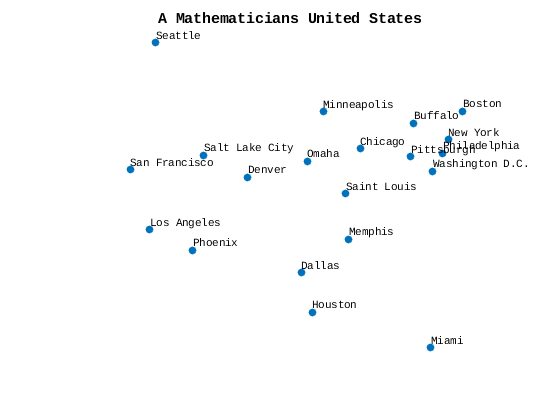

k = 2;
[D, city] = citydist();

D = D.^2;
n = length(D);

H = eye(n) - ones(n)/n;
B = -H*D*H/2;
[U,S,v] = svd(B);

figure()
X = U(:,1:k)*S(1:k,1:k).^(1/2);
scatter(X(:,1),X(:,2),'filled')
title('A Mathematicians United States')
set(gca, 'YDir','reverse')
set(gca, 'XDir','reverse')
axis off
text(X(:,1),X(:,2),city,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8) 

MDS was able to reconstruct the U.S. map with visual accuracy! We can see Miami in the bottom right where Florida should be, and Minneapolis is top and center in the approximate place of Minnesota. Most of the boardering cities match the coastlines and all!

# Problem 2

## (a) Functions Made

## (b)

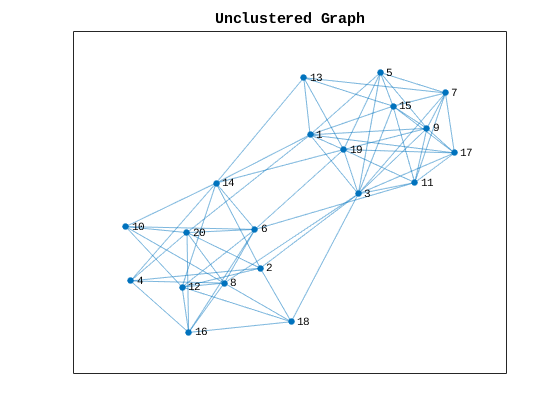

N = 10; % we’ll generate two clusters, each with 10 nodes
A = zeros(2*N, 2*N);
rand('state',100);
for i = 1:2*N-1
    for j = i+1:2*N
        p = 0.7 - 0.6*mod(j-i,2);
        A(i,j) = rand<p;
    end
end
A = A + A';
figure(1), clf
plotA = plot(graph(A));
title('Unclustered Graph')

Visually, we can see two cluster, one in the top right and one in the bottom left. So, when we apply the spectral clustering, we should get recover those two clusters.

## (c)

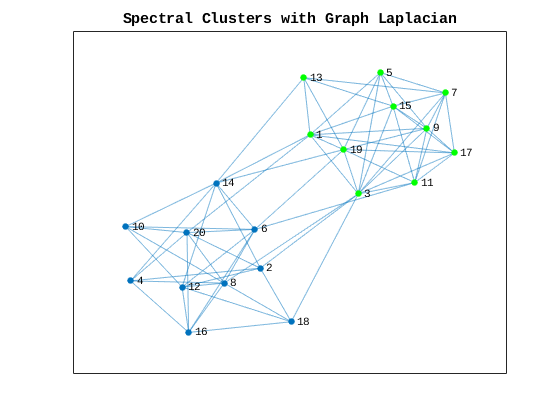

n = length(A);
L = get_laplacian(A);
D = get_degree(A);

[V,E] = eig(L,D);
fied = sign(V(:,2));

figure()
N = 10; % we’ll generate two clusters, each with 10 nodes
A = zeros(2*N, 2*N);
rand('state',100);
for i = 1:2*N-1
    for j = i+1:2*N
        p = 0.7 - 0.6*mod(j-i,2);
        A(i,j) = rand<p;
    end
end
A = A + A';
figure(1), clf
plotA = plot(graph(A));
title('Spectral Clusters with Graph Laplacian')

colors = zeros(n,1);
highlight(plotA, find(fied == 1), 'NodeColor','g')

As expected, the spectral clustering algorithm was able to distinguish between the two heavily connected clusters.

## (d)

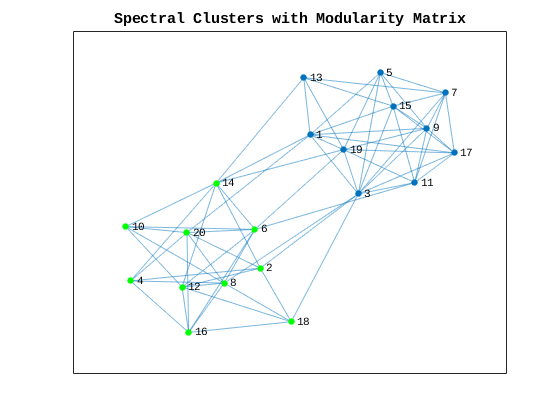

n = length(A);
M = get_modularity(A);
D = get_degree(A);

[V,E] = eig(M,D);
fied = sign(V(:,end));

figure()
N = 10; % we’ll generate two clusters, each with 10 nodes
A = zeros(2*N, 2*N);
rand('state',100);
for i = 1:2*N-1
    for j = i+1:2*N
        p = 0.7 - 0.6*mod(j-i,2);
        A(i,j) = rand<p;
    end
end
A = A + A';
figure(1), clf
plotA = plot(graph(A));
title('Spectral Clusters with Modularity Matrix')

colors = zeros(n,1);
highlight(plotA, find(fied == 1), 'NodeColor','g')

Just as before, using the modularity matrix for clustering produced the same clusters with the only difference being in what sign of the Fiedler vector represented which cluster. This difference is most likely due to the eigenvector solver; eigenvectors are still eigenvectors under negation.

# Functions

function [D] = get_degree(A)
d = sum(A,2);
    
    D = diag(d);
end

function [L] = get_laplacian(A)
    D = get_degree(A);
    
    L = D - A;
end

function [M] = get_modularity(A)
    d = sum(A,2);
    
    M = A - d*d'/(sum(d));
end